%Trapezoid Rule
clear all;
close all;
clc;

% define the function of a = 7 * t^4
acc = @(t) 7.*t.*t.*t.*t;

% set the time range(s) and initial velocity (m/s)
ti = 0;
tf = 4;
vel_initial = 100;

% set the number of intervals
n = 40;

% set up the time vector and the acceleration at each of the time values
time = linspace(ti,tf,n+1) % 1 interval, 2 points, so n+1

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


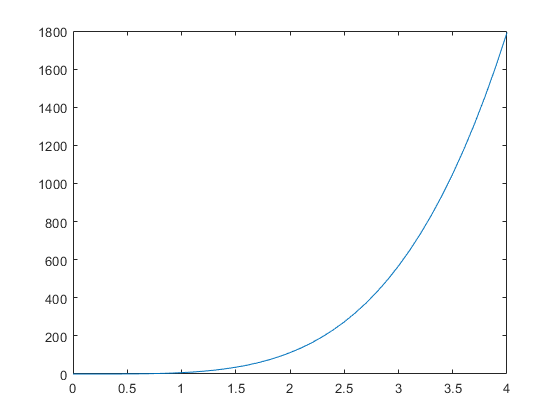

accel = acc(time);
plot(time,accel)


% using trapezoid rule
% numerical integration using trapezoid rule
integrationTrap = 0;

delta_time = (tf-ti)/n;
area_beneath_curve = (delta_time/2)*(accel(n+1)+accel(1));

for i = 2:n
    area_beneath_curve = area_beneath_curve + delta_time * accel(i);
end

vel_final_trapezoid = vel_initial + area_beneath_curve

vel_final_trapezoid = 1.5351e+03


% numerical integration using trapz, built in matlab function
v_final_trapz = vel_initial + trapz(time,accel)

v_final_trapz = 1.5351e+03


% exact solution
v_final_exact = 100 + ((7*4^5)/5);

%Difference
DiffTrap = 100 * (v_final_exact - vel_final_trapezoid)/v_final_exact

DiffTrap = -0.0974